# XFOIL Proof

syms x
v = 2.602e-5;
Uinf = 178.816; %m/s
cf_turb = @(x) 0.0592*v^0.2/(Uinf*x)^0.2;
Cdwing = vpa((2/3.5)*int(cf_turb,x,0,3.5),4)

$$Cdwing = 0.004943$$

# Compressability Proof 

clc
clear
 
M = 0.3:0.1:0.8; 
m = mfoil('naca','4412', 'npanel',199);

%compressable flow over mach
for i = 1:1:6
    %set parameters 
    m.setoper('alpha',0, 'Ma',M(i));
    % run the solver, plot the results 
    m.solve;
    Cd_Mfoil(i) = m.post.cd;
end 


 <<< Solving inviscid problem >>> 
  alpha=0.00deg, cl=0.541872, cm=-0.117372, cdpi=-0.001900, cd=0.000000, cdf=0.000000, cdp=0.000000

 <<< Solving inviscid problem >>> 
  alpha=0.00deg, cl=0.570644, cm=-0.122779, cdpi=-0.002651, cd=0.000000, cdf=0.000000, cdp=0.000000

 <<< Solving inviscid problem >>> 
  alpha=0.00deg, cl=0.614777, cm=-0.130938, cdpi=-0.003870, cd=0.000000, cdf=0.000000, cdp=0.000000

 <<< Solving inviscid problem >>> 
  alpha=0.00deg, cl=0.684206, cm=-0.143457, cdpi=-0.005936, cd=0.000000, cdf=0.000000, cdp=0.000000

 <<< Solving inviscid problem >>> 
  alpha=0.00deg, cl=0.802775, cm=-0.163996, cdpi=-0.009835, cd=0.000000, cdf=0.000000, cdp=0.000000

 <<< Solving inviscid problem >>> 
  alpha=0.00deg, cl=1.046679, cm=-0.203252, cdpi=-0.019045, cd=0.000000, cdf=0.000000, cdp=0.000000


display(Cd_Mfoil)

Cd_Mfoil =      0     0     0     0     0     0



 <<< Solving inviscid problem >>> 
  alpha=0.00deg, cl=0.541872, cm=-0.117372, cdpi=-0.001900, cd=0.000000, cdf=0.000000, cdp=0.000000

 <<< Initializing the boundary layer >>> 
  transition on lower side at x=0.33688
  transition on upper side at x=0.48662

 <<< Beginning coupled solver iterations >>> 
  transition on lower side at x=0.33688
  transition on upper side at x=0.48662
  alpha=0.00deg, cl=0.521160, cm=-0.111582, cdpi=-0.003983, cd=0.011119, cdf=0.006507, cdp=0.004612

Newton iteration 1, Rnorm = 1.10683e-01
  transition on lower side at x=0.33059
  transition on upper side at x=0.49236
  alpha=0.00deg, cl=0.497308, cm=-0.106918, cdpi=-0.002870, cd=0.010685, cdf=0.006446, cdp=0.004239

Newton iteration 2, Rnorm = 5.21760e-01
  transition on lower side at x=0.32416
  transition on upper side at x=0.49883
  alpha=0.00deg, cl=0.479748, cm=-0.103357, cdpi=-0.002288, cd=0.010375, cdf=0.006506, cdp=0.003869

Newton iteration 3, Rnorm = 6.06176e-01
  transition on lower side at x

  transition on upper side at x=0.52459
  alpha=0.00deg, cl=0.533337, cm=-0.114102, cdpi=-0.001693, cd=0.008447, cdf=0.006342, cdp=0.002105

Newton iteration 8, Rnorm = 5.17406e-01
  transition on lower side at x=0.27738
  transition on upper side at x=0.52593
  alpha=0.00deg, cl=0.544020, cm=-0.115917, cdpi=-0.001780, cd=0.007508, cdf=0.005674, cdp=0.001834

Newton iteration 9, Rnorm = 3.50866e-01
  transition on lower side at x=0.27553
  transition on upper side at x=0.54158
  alpha=0.00deg, cl=0.537694, cm=-0.114766, cdpi=-0.001748, cd=0.007950, cdf=0.005945, cdp=0.002005

Newton iteration 10, Rnorm = 8.19947e-02
  transition on lower side at x=0.27678
  transition on upper side at x=0.54313
  alpha=0.00deg, cl=0.542272, cm=-0.115683, cdpi=-0.001785, cd=0.007991, cdf=0.006006, cdp=0.001985

Newton iteration 11, Rnorm = 1.01672e-02
  transition on lower side at x=0.27760
  transition on upper side at x=0.54384
  alpha=0.00deg, cl=0.542593, cm=-0.115763, cdpi=-0.001783, cd=0.008001, c



%incompressable flow over mach with PrandtlG scaling
for i = 1:1:6
    %set parameters 
    m.setoper('alpha',0, 'Re',10^6, 'Ma',M(i));
    % run the solver, plot the results 
    m.solve;
    Cd_prandtlG(i) = m.post.cd/sqrt(1-M(i)^2);
end 

display(Cd_prandtlG)

Cd_prandtlG =     0.0076    0.0083    0.0092    0.0107    0.0133    0.0191


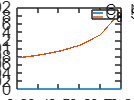




% figure 
% plot(M,Cd_Mfoil)
% hold on 
% plot(M,Cd_prandtlG)
% hold off
% ylabel('Cd')
% xlabel('Mach')
% legend("C_d Mfoil","C_d Scaled")

# AVL Proof